# **Tutorial 14**: Kinematic and dynamic models and control of a planar 3 d.o.fs flexible arm ( $\approx 4\;mn$ run).

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Description

Let us consider the 3 degrees-of-freedom (d.o.f) flexible robotic arm described in the following Figure and working in the horizontal plane $(P_1,\mathbf x_0, \mathbf y_0)$ (no gravity effect). This arm is composed of :

- 3 flexible links $\mathcal L_i$  between point $P_i$ and $C_i$ connected by revolute joints at the points $P_i$, $i=1,2,3$,

- 2 local masses $m_1$ and $m_2$ at the tips $C_1$ and $C_2$ of the links $\mathcal L1$ and $\mathcal L_2$.

 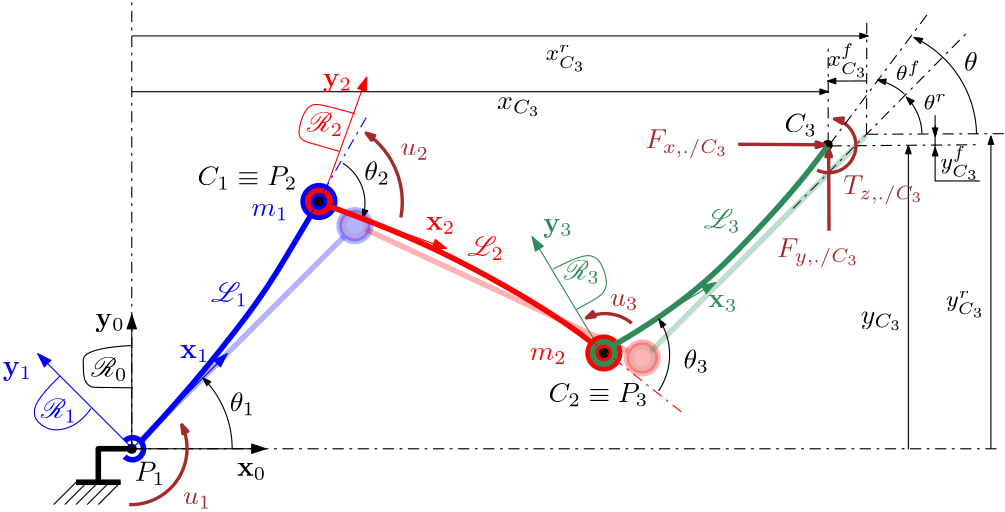

$\mathcal R_0$ is the frame attached to the ground (also called link $\mathcal L_0$) and $\mathcal R_i$ is the frame attached to the link $\mathcal L_i$.

$\mathbf \theta=[\theta_1\quad \theta_2 \quad \theta_3]^T$ is the geometric configuration of the arm.

The first objective is to compute $6 \times 6$ dynamic model $\mathbf G(\mathrm s,\mathbf\theta)$ between:

- the 6 inputs composed of the $3$ joint torques $\mathbf u=[u_1\quad u_2\quad u_3]^T\;(Nm)$ and the $3$ components of the planar external wrench $F_{x,./C_3}\,(N)$, $F_{y,./C_3}\,(N)$ and $T_{z,./C_3}\,(Nm)$ which can be applied at the point $C_3$ and projected in the frame $\mathcal R_0$,

- the 6 outputs composed of the $3$ in-joint acceleration $\ddot\mathbf\theta=[\ddot\theta_1 \quad \ddot\theta_2 \quad \ddot\theta_3]^T$ and the $3$ components of the planar acceleration dual vector $\ddot x_{C_3}\,(m/s^2)$, $\ddot y_{C_3}\,(m/s^2)$ and $\ddot\theta$ at the point $C_3$ and projected in the frame $\mathcal R_0$.

Since the input and output ports of the various blocks of the` SDTlib `consider the $6$ d.o.f.s case, the $3$ d.o.f relative to the $\mathbf x\mathbf y$-plane (i.e. the translation along $\mathbf x$, the translation along $\mathbf y$ and the rotation around $\mathbf z$) are the components $1$, $2$ and $6$ of the dual vectors used in the TITOP models and we will denote the $\mathbf{xy}$-plane dual vectors:

- $\left[\begin{array}{c}\ddot x_{C_3} \\ \ddot y_{C_3} \\ \dot\theta\end{array}\right]=[\mathbf{ x''}^{\mathcal L_3}_{C_3}([1,2,6])]_{\mathcal R_{0}}$,

- $\left[\begin{array}{c}F_{x,./C_3} \\ F_{y,./C_3} \\ T_{z,./C_3} \end{array}\right]=[\mathbf W_{ext/\mathcal L_3,C_3}([1,2,6])]_{\mathcal R_{0}}$.

The second objective is to compute the kinematic model (or Jacobian) of the robotic arm, that is to say:  for a given nominal angular configuration $\mathbf \theta$ of the robotic arm, the $3\times 3$ matrix $\mathbf J(\mathbf\theta)$ between the $3$ joint angular rates $\mathbf{\dot\theta}=[\dot\theta_1\quad \dot\theta_2 \quad \dot\theta_3]^T$ and the planar twist $[\delta\mathbf{ x'}^r_{C_3}([1,2,6])]_{\mathcal R_{0}}$ at the end-effector point $C_3$ and projected in the ground frame $\mathcal R_{0}$ assuming that the robotic arm is rigid:


$$[\delta\mathbf{ x'}^r_{C_3}([1,2,6])]_{\mathcal R_{0}}=\mathbf J(\mathbf\theta)\dot\mathbf\theta$$


with $[\delta\mathbf{ x}^r_{C_3}([1,2,6])]_{\mathcal R_{0}}=\left[\begin{array}{c}x^r_{C_3} \\  y^r_{C_3} \\ \theta^r\end{array}\right]$ (see Figure).

**Remark: **Let us consider the non-linear geometric model between the absolute position/attitude of the point $C_3$ in the frame $\mathcal R_0$ $[\mathbf x^r_{C_3}([1,2,6])]_{\mathcal R_{0}}$ and the arm geometric configuration $\mathbf \theta$ when the robotic arm is rigid: 

$[\delta\mathbf x^r_{C_3}([1,2,6])]_{\mathcal R_{0}}=\mathcal G(\mathbf\theta)$. 

For the considered example, this geometric model reads:


$$\left\{\begin{array}{rcl} x^r_{C_3} & =& l_1\cos\theta_1 + l_2\cos(\theta_1+\theta_2)+ l_3\cos(\theta_1+\theta_2+\theta_3)\\  y^r_{C_3}& = & l_1\sin\theta_1 + l_2\sin(\theta_1+\theta_2)+ l_3\sin(\theta_1+\theta_2+\theta_3) \\ \theta^r& =  & \theta_1+\theta_2+\theta_3\end{array}\right.$$


where $l_i$ is the length of link $\mathcal L_i$, $i=1,2,3$.

Its time-domain derivation allows the Jacobian to be derived: $\mathbf J(\mathbf\theta)=\frac{\partial\mathcal G(\mathbf\theta)}{\partial\mathbf\theta}^T=\left[\frac{\partial\mathcal G}{\partial\theta_1}\quad\frac{\partial\mathcal G}{\partial\theta_2} \quad\frac{\partial\mathcal G}{\partial\theta_3} \right]$.  For the considered example:

$\mathbf J(\mathbf\theta)=\left[\begin{array}{ccc}-l_1\sin\theta_1-l_2\sin(\theta_1+\theta_2)-l_3\sin(\theta_1+\theta_2+\theta_3) & -l_2\sin(\theta_1+\theta_2)-l_3\sin(\theta_1+\theta_2+\theta_3) &  -l_3\sin(\theta_1+\theta_2+\theta_3)\\ l_1\cos\theta_1+l_2\cos(\theta_1+\theta_2)+l_3\cos(\theta_1+\theta_2+\theta_3) & l_2\cos(\theta_1+\theta_2)+l_3\cos(\theta_1+\theta_2+\theta_3) &  l_3\cos(\theta_1+\theta_2+\theta_3)\\ 1 & 1 & 1\end{array}\right]$.

Since only the first order terms are considered, the kinematic model works also on the accelerations: 


$$[\delta\mathbf{ x''}^r_{C_3}([1,2,6])]_{\mathcal R_{0}}=\mathbf J(\mathbf\theta)\mathbf{\ddot\theta}$$


(the second order terms in $\frac{\partial\mathbf J(\mathbf\theta)}{\partial \theta_i}\dot\theta_i\mathbf{\dot\theta}\;,\;\;i=1,\cdots 3$, due to the time-derivation are neglected). 

The transposed of the kinematic model $\mathbf J(\mathbf\theta)^T$ describes also the relation from the planar wrench $[\mathbf W^r_{\mathcal L_3/ext,C_3}([1,2,6])]_{\mathcal R_0}$ applied by the end effector (and working along $\mathbf{\Delta x}$) to the input vector $\mathbf u=[u_1,\;\;u_2,\;\;u_3]^T$ of the local torques applied inside the arm joints (and working along $\mathbf{\Delta\theta}$): 

$\mathbf u=J(\mathbf\theta)^T[\mathbf W^r_{\mathcal L_3/ext,C_3}([1,2,6])]_{\mathcal R_0}$.

The `SDTlib `models considers the transfer from wrenches to [motion vector](matlab:open('../SDTfct/doc_SDTlib/doc_BODIES/doc_hub/DocGeneralNotations.html'))  (18 components = 6 DoFs accelerations , 6 DoFs velocities and 6 DoFs positions).  When this model is restricted to the acceleration dual vectors (6 components), the tranfers from wrenches to accelerations can be inverted thanks to channel inversion operations. Since only the rigid behavior must be only considered to compute the kinematic model (the kinematic model does not depend on the flexible states), this kinematic model can be directly computed from the DC-gain of the` SDTlib` model and a judicious channel inversion. That is ilustrated in the subsections 3.

**Numerical application:** 

- The links have the same length $l_1=l_2=l_3=l=1\,m$ and the same square section of $1\,cm$ on each side. There are made of aluminium,

- $m_1=m_2=m=1\,Kg$.

## 2. Dynamic model

The 6 d.o.f. flexible beams $\mathcal L_i$ can modelled in the SDTlib with the bock `2 ports flexible beam` of the sub-library `6 dof bodies`  or with the block  `TITOP flexible beam+revolute joint`  (which takes into account a revolute joint at one tip of the beam and thus will be prefered in this example) of the library` Predefined subsystems`. 

web DocBeam.html -new
web DocBeamRevolute.html -new

This model is expressed in the local frame $\mathcal R_{i}=(\mathbf x_{i}, \mathbf y_{i}, \mathbf z_{i})$ of the beam assuming that $\mathbf x_{i}$is along the beam axis. This model considers 4 bending modes in the plane ($\mathbf x_{i},\mathbf y_{i}$), 4 bending modes in the plane ($\mathbf x_{i},\mathbf z_{i}$), 1 torsion mode around $\mathbf x_{i}$ and one traction mode along $\mathbf x_{i}$. Thus 5 out-of-plane flexible modes (bending in the plane ($\mathbf x_{i},\mathbf z_{i}$) and torsion around $\mathbf x_i$) per link must be reduced when considering the motion in $\mathbf x\mathbf y$-plane.

The next figure displays the dialog box relative to the link $\mathcal L_1$where the mass density and Young modulus correspond to aluminium and the angular configuration is declared as a varying parameters to cover a whole revolution $\theta_1 \in\,[-\pi,\;\pi]$.

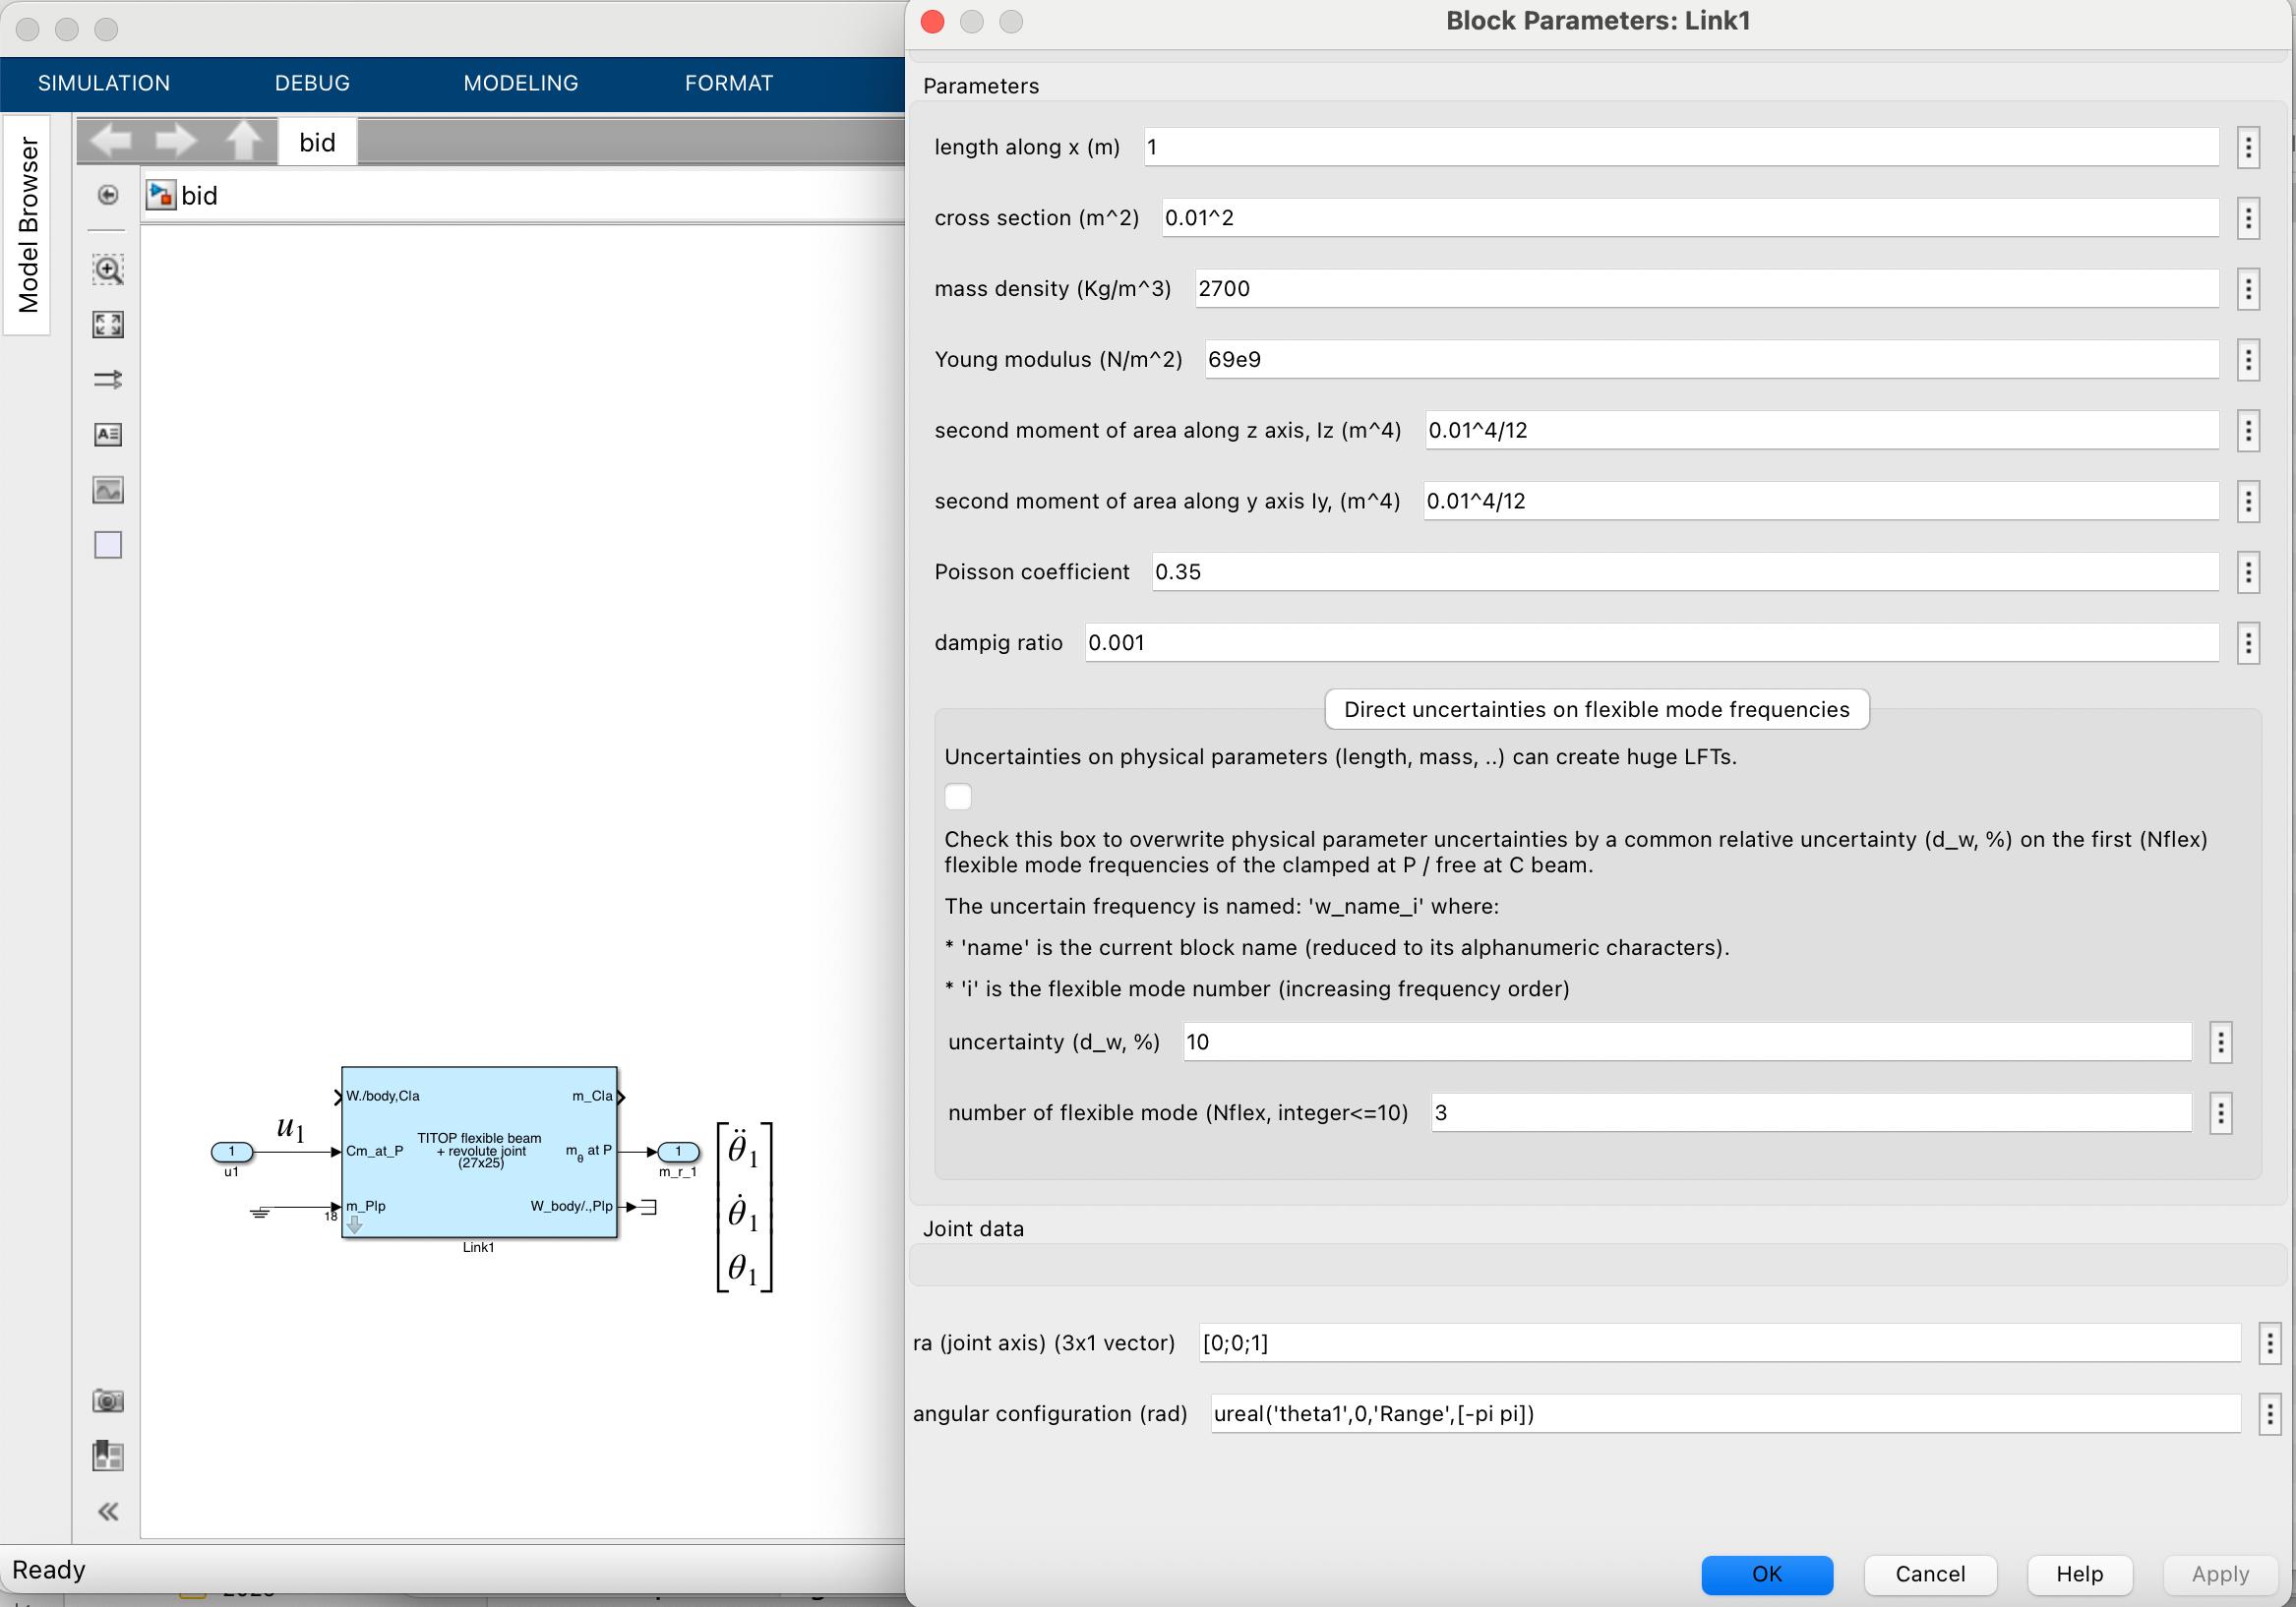

The tip mass $m_1$ is modelled by a` Multi-port rigide body` block connected to the free tip $C_1$ of the link $\mathcal L_1$according to the follwing Figure.

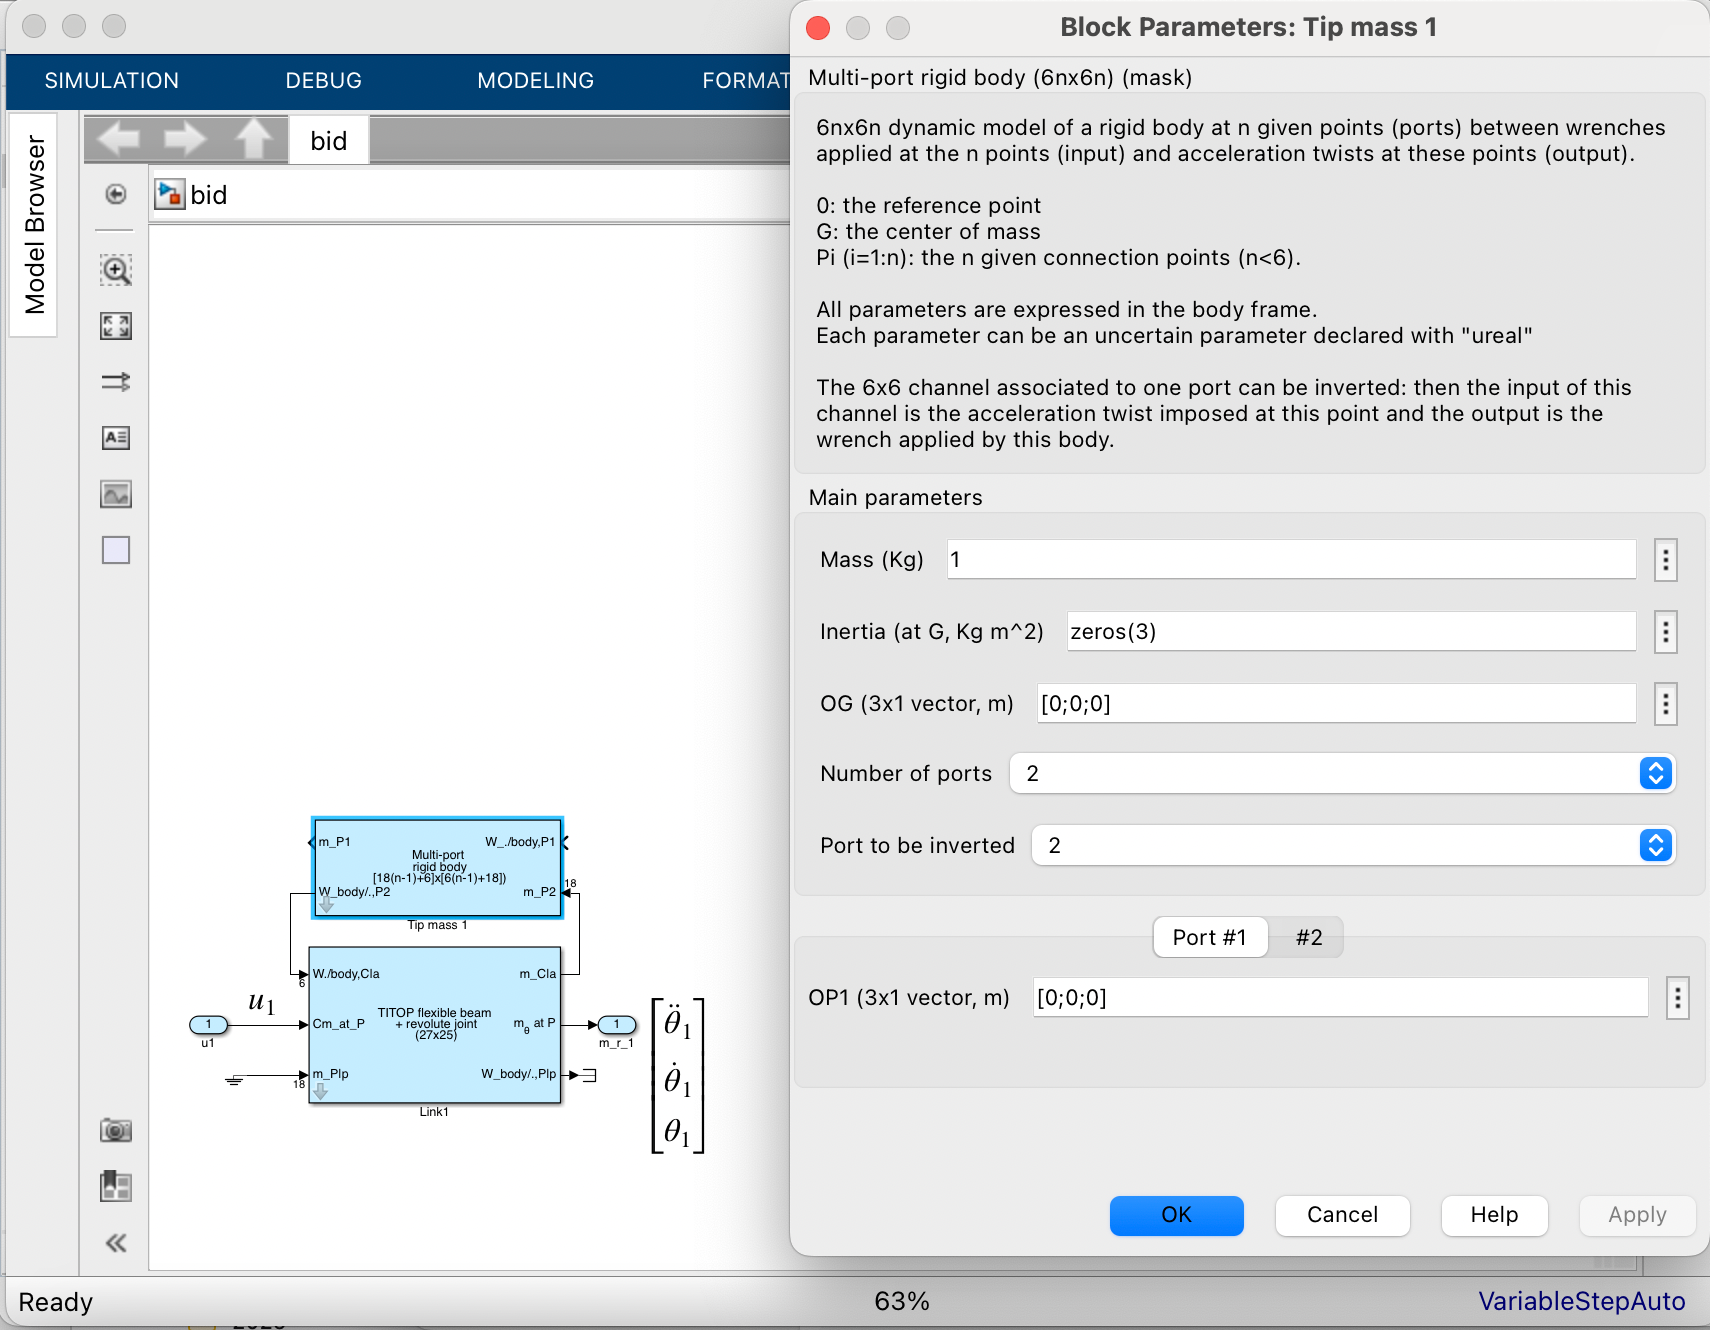

The same procedure can be applied to the links $\mathcal L_2$ and $\mathcal L_3$. The model of whole system is then represented by the SIMULINK file `PlanarArmAug.slx.` It is completed by the DCMs (Direction Cosine Matrices) :

$\mathbf P_{i/i-1}=\left[\begin{array}{ccc}\cos\theta_1 & -sin\theta_i & 0\\ \sin\theta_i & \cos \theta_i & 0\\0 & 0 &1\end{array}\right]$ between frame $\mathcal R_i$ and $\mathcal R_{i-1}$ to transform the $\mathbf x\mathbf y$-plane dual vectors projected in $\mathcal R_0$ into the 6 d.o.f. dual vectors projected in the frame $\mathcal R_3$ . Indeed the dual vectors on the outputs or the inputs of the body TITOP model are always expressed in the body frame.

PlanarArmAug

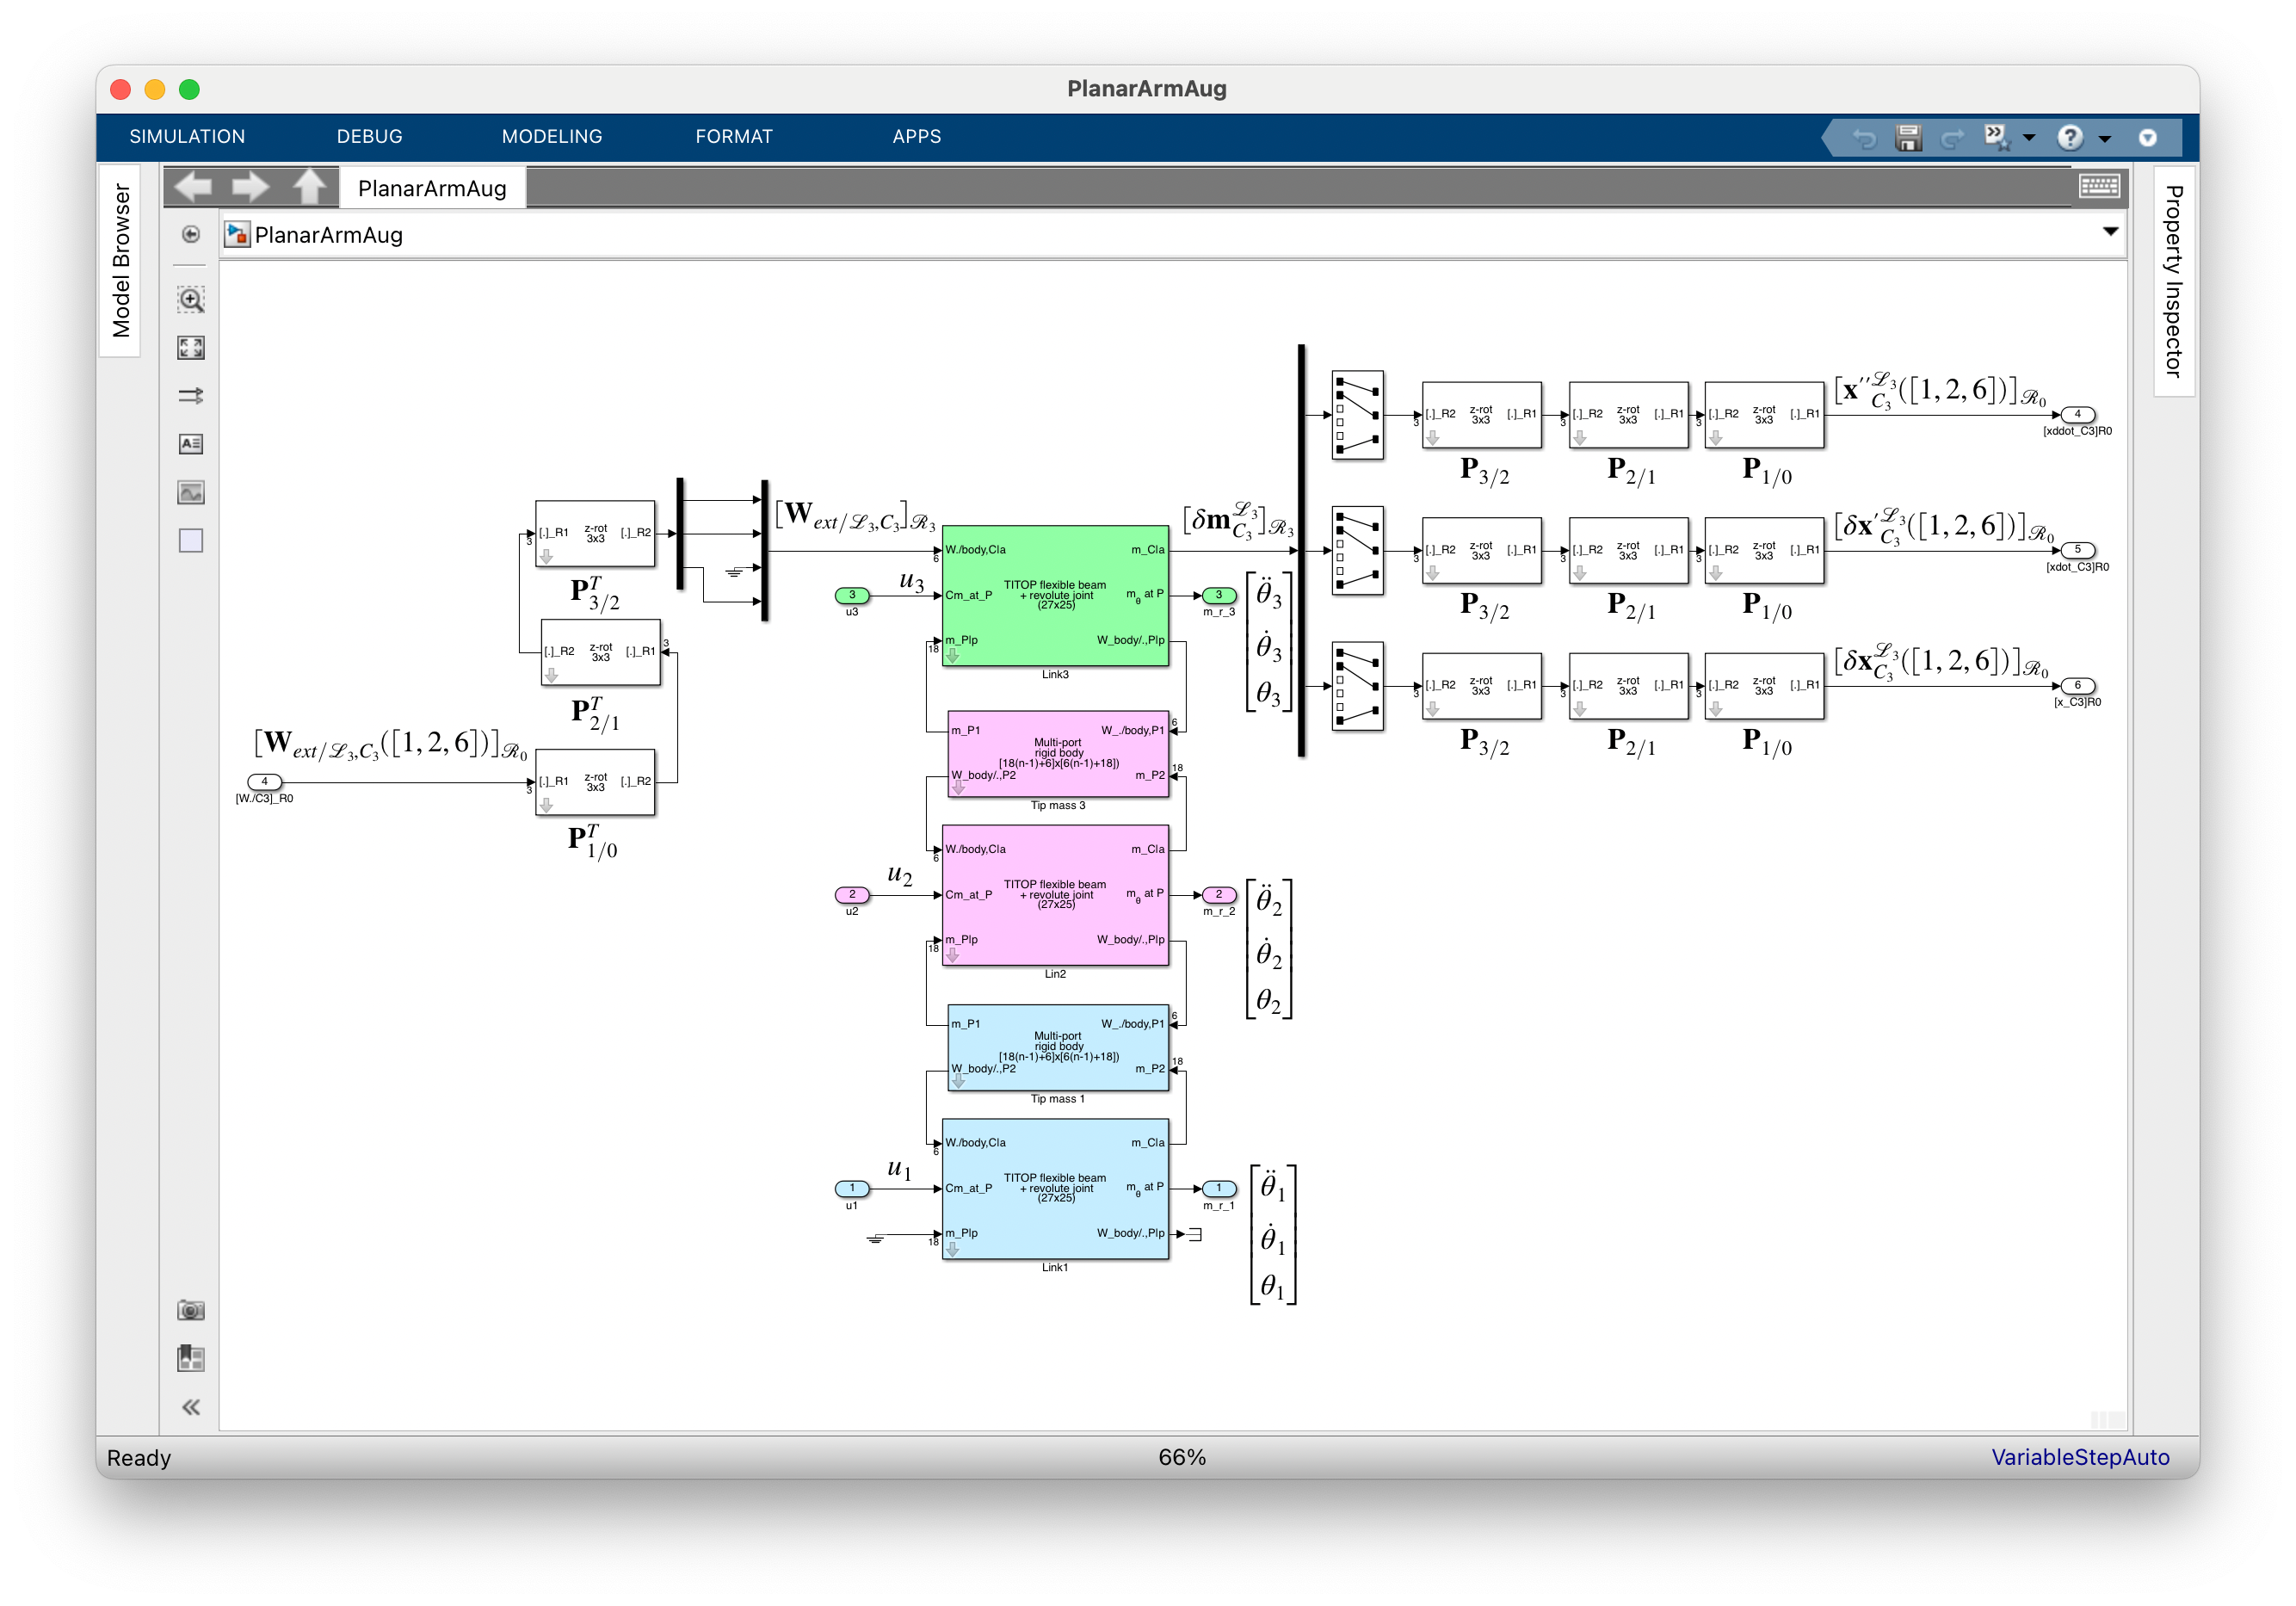

One can then compute the full dynamic $18\times 6$ model $\mathbf G_f(\mathrm s,\mathbf\theta)$ between from the  wrench and the in-joint torques to the $\mathbf{xy}$-plane motion vector and the joint relative motion vectors:

Gfu=ulinearize('PlanarArmAug')

Gfu =

  Uncertain continuous-time state-space model with 18 outputs, 6 inputs, 66 states.
  The model uncertainty consists of the following blocks:
    tan_theta1_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 40 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 40 occurrences

Type "Gfu.NominalValue" to see the nominal value, "get(Gfu)" to see all properties, and "Gfu.Uncertainty" to interact with the uncertain elements.



Depending on the Matlab version, the `ulinearize` function provides the full order model or the reduced order model where the out-of-plane flexible modes are reduced. The full model order is $66$ due to the $3$ flexible beams and the $10$ flexible modes (20 state variables) per beam and the 3 rigid modes ( $6$ poles at $0$). The reduced model order is $36$ since $5$ out-of plane flexible modes per beam (bending in the plane ($\mathbf x_{i},\mathbf z_{i}$) and torsion around $\mathbf x_i$) can be reduced. The reduced order model can be found using the `sminreal` function:

Gfu=sminreal(Gfu)

Gfu =

  Uncertain continuous-time state-space model with 18 outputs, 6 inputs, 36 states.
  The model uncertainty consists of the following blocks:
    tan_theta1_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 32 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 32 occurrences

Type "Gfu.NominalValue" to see the nominal value, "get(Gfu)" to see all properties, and "Gfu.Uncertainty" to interact with the uncertain elements.



One can then compute the model $\mathbf G(\mathrm s,\mathbf\theta)$ restricted to the acceleration outputs:

Gu=sminreal(Gfu([1 4 7 10:12],:))

Gu =

  Uncertain continuous-time state-space model with 6 outputs, 6 inputs, 30 states.
  The model uncertainty consists of the following blocks:
    tan_theta1_div4: Uncertain real, nominal = 0, range = [-1,1], 8 occurrences
    tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 16 occurrences

Type "Gu.NominalValue" to see the nominal value, "get(Gu)" to see all properties, and "Gu.Uncertainty" to interact with the uncertain elements.



 and the dynamics of the model in the deployed configuration ( $\theta_i=0,\;i=1,2,3$) . This dynamics is composed of $n=15$ flexible modes (the $3$ rigid modes are reduced since we consider only the accelerations:

damp(Gu)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.18e-01 + 1.45e+02i     1.50e-03       1.45e+02         4.58e+00    
 -2.18e-01 - 1.45e+02i     1.50e-03       1.45e+02         4.58e+00    
 -2.41e-01 + 1.53e+02i     1.57e-03       1.53e+02         4.14e+00    
 -2.41e-01 - 1.53e+02i     1.57e-03       1.53e+02         4.14e+00    
 -6.32e-01 + 2.29e+02i     2.75e-03       2.29e+02         1.58e+00    
 -6.32e-01 - 2.29e+02i     2.75e-03       2.29e+02         1.58e+00    
 -1.93e+00 + 5.80e+02i     3.34e-03       5.80e+02         5.17e-01    
 -1.93e+00 - 5.80e+02i     3.34e-03       5.80e+02         5.17e-01    
 -1.99e+00 + 5.89e+02i     3.39e-03       5.89e+02         5.02e-01    
 -1.99e+00 - 5.89e+02i     3.39e-03       5.89e+02         5.02e

and plot the frequency domaine (magnitude) of the $3\times 3$ dynamic model seen from the joints, i.e the transfer from $\mathbf u$ to $\ddot\mathbf\theta$ for some randomly sampled geometric configurations:

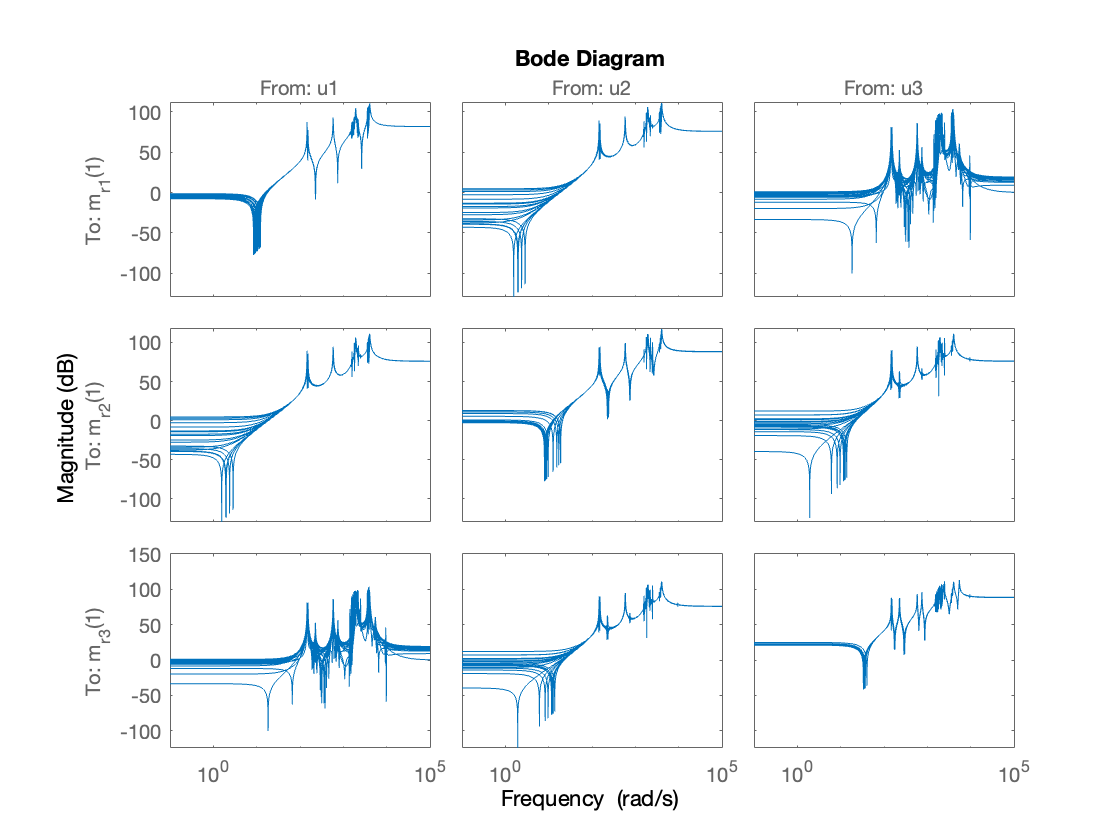

figure
bodemag(Gu(1:3,1:3))

Obviously this $3\times 3$ "joint" model does not depend on $\theta_1$:

Gu(1:3,1:3)

ans =

  Uncertain continuous-time state-space model with 3 outputs, 3 inputs, 30 states.
  The model uncertainty consists of the following blocks:
    tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 8 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 8 occurrences

Type "ans.NominalValue" to see the nominal value, "get(ans)" to see all properties, and "ans.Uncertainty" to interact with the uncertain elements.



On can also compute the "Joint" mass matrix $\mathbf I_0\,(Kg\,m^2)$ in the deployed configuration ( $\theta_i=0,\;i=1,2,3$) as the inverse of the DC-gain of this model:

I0=inv(dcgain(Gu(1:3,1:3)))  % kg m^2

I0 =     7.4300    3.2600    0.3600
    3.2600    1.7200    0.2250
    0.3600    0.2250    0.0900


## 3. Kinematic model

To compute the kinematic model $\mathbf J(\mathbf\theta)$ from the equation on the accelerations: $[\delta\mathbf{ x''}^r_{C_3}([1,2,6])]_{\mathcal R_{0}}=\mathbf J(\mathbf\theta)\mathbf{\ddot\theta}$, one can just inverse the channel 1 to 3 of the model $\mathbf G(\mathrm s,\mathbf\theta)$ so that the 3 first new inputs of the inverted model $\mathbf G^{-1_{[1:3]}}(\mathrm s,\mathbf\theta)$ are $\ddot\mathbf\theta$. $\mathbf J(\mathbf\theta)$ is then the DC-gain of the transfer from inputs 1 to 3 to the outputs 4 to 6 of $\mathbf G^{-1_{[1:3]}}(\mathrm s,\mathbf\theta)$. 

One have to compute the DC-gain from the state-space matrices since the matlab function` dcgain` does not support `uss` object. That can lead to huge LFT and it is recommanded to simplify them:

Gum1=invio(Gu,1:3);
Jacobu=Gum1.D(4:6,1:3)-Gum1.C(4:6,:)*inv(Gum1.A)*Gum1.B(:,1:3)

Jacobu =

  Uncertain matrix with 3 rows and 3 columns.
  The uncertainty consists of the following blocks:
    tan_theta1_div4: Uncertain real, nominal = 0, range = [-1,1], 8 occurrences
    tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 40 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 40 occurrences

Type "Jacobu.NominalValue" to see the nominal value, "get(Jacobu)" to see all properties, and "Jacobu.Uncertainty" to interact with the uncertain elements.



Jacobu=simplify(Jacobu,'full')

Jacobu =

  Uncertain matrix with 3 rows and 3 columns.
  The uncertainty consists of the following blocks:
    tan_theta1_div4: Uncertain real, nominal = 0, range = [-1,1], 4 occurrences
    tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 36 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 34 occurrences

Type "Jacobu.NominalValue" to see the nominal value, "get(Jacobu)" to see all properties, and "Jacobu.Uncertainty" to interact with the uncertain elements.



Considering the non-singluar configuration $\mathbf \theta_0=[\pi/4\quad -\pi/2\quad \pi/4]$, one can evaluate the kinematic model `Jacobu`: 

Theta0=[pi/4;-pi/2;pi/4];
Jacob0=usubs(Jacobu,'tan_theta1_div4',tan(Theta0(1)/4),...
                    'tan_theta2_div4',tan(Theta0(2)/4),...
                    'tan_theta3_div4',tan(Theta0(3)/4))

Jacob0 =     0.0000    0.7071    0.0000
    2.4142    1.7071    1.0000
    1.0000    1.0000    1.0000


and compared it with the analytical value previously characterized $\mathbf J(\mathbf\theta_0)$:

Jana=[-sin(Theta0(1))-sin(Theta0(1)+Theta0(2))-sin(Theta0(1)+Theta0(2)+Theta0(3)) ...
      -sin(Theta0(1)+Theta0(2))-sin(Theta0(1)+Theta0(2)+Theta0(3)) -sin(Theta0(1)+Theta0(2)+Theta0(3));...
       cos(Theta0(1))+cos(Theta0(1)+Theta0(2))+cos(Theta0(1)+Theta0(2)+Theta0(3)) ...
       cos(Theta0(1)+Theta0(2))+cos(Theta0(1)+Theta0(2)+Theta0(3)) cos(Theta0(1)+Theta0(2)+Theta0(3));...
       1 1 1]

Jana =          0    0.7071         0
    2.4142    1.7071    1.0000
    1.0000    1.0000    1.0000


One can check that we have the same results.

One can also compute  $\mathbf J(\mathbf\theta)^T$ by the "transposed"  relation on the wrenches (with a minus sign on the last inputs corresponding to $[\mathbf W_{ext/\mathcal L_3,C_3}([1,2,6])]_{\mathcal R_{0}}$):

JacobuT=-Gum1.D(1:3,4:6)+Gum1.C(1:3,:)*inv(Gum1.A)*Gum1.B(:,4:6);
JacobuT=simplify(JacobuT,'full')

JacobuT =

  Uncertain matrix with 3 rows and 3 columns.
  The uncertainty consists of the following blocks:
    tan_theta1_div4: Uncertain real, nominal = 0, range = [-1,1], 4 occurrences
    tan_theta2_div4: Uncertain real, nominal = 0, range = [-1,1], 36 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0, range = [-1,1], 40 occurrences

Type "JacobuT.NominalValue" to see the nominal value, "get(JacobuT)" to see all properties, and "JacobuT.Uncertainty" to interact with the uncertain elements.



and checks it provides the same result on the proposed configuration:

Jacobu0T=usubs(JacobuT,'tan_theta1_div4',tan(Theta0(1)/4),...
                       'tan_theta2_div4',tan(Theta0(2)/4),...
                       'tan_theta3_div4',tan(Theta0(3)/4));
Jacobu0T'

ans =    -0.0000    0.7071    0.0000
    2.4142    1.7071    1.0000
    1.0000    1.0000    1.0000


## 4. Inverse kinematic model $\mathbf J(\mathbf\theta)^{-1}$

In the next sections, we will require to inverse the jacobian $\mathbf J(\mathbf\theta)$. Since its is obvious that in the extented configuration, corresponding to the nominal configuration of the LFT` Jacobu`, $\mathbf J(\mathbf 0)$ is singular:

Jacobu.NominalValue

ans =     0.0000    0.0000   -0.0000
    3.0000    2.0000    1.0000
    1.0000    1.0000    1.0000


it is recommanded to change the nominal configuation of the robotic arm to computed the LFT associated to $\mathbf J(\mathbf\theta)^{-1}$.

Indeed, evaluating` inv(Jacobu) `on the previous configuration $\mathbf \theta_0$:

usubs(inv(Jacobu),'tan_theta1_div4',tan(Theta0(1)/4),...
                  'tan_theta2_div4',tan(Theta0(2)/4),...
                  'tan_theta3_div4',tan(Theta0(3)/4))

ans =    -2.1719    1.3413   -0.5373
    4.4688   -1.3025   -0.4247
   -2.6094    0.1354    1.9773


inv(Jacob0)

ans =    -0.7071    0.7071   -0.7071
    1.4142   -0.0000    0.0000
   -0.7071   -0.7071    1.7071


highlights that `inv(Jacobu)`is wrong.

One can the use the nominal configuration $\mathbf\theta_0$, to do the inversion:

Jacobu.Blocks.tan_theta1_div4.NominalValue=tan(Theta0(1)/4);
Jacobu.Blocks.tan_theta2_div4.NominalValue=tan(Theta0(2)/4);
Jacobu.Blocks.tan_theta3_div4.NominalValue=tan(Theta0(3)/4);
JacobuInv=inv(Jacobu);

and check that the inversion is correct on the nominal configuration $\mathbf\theta_0$:

JacobuInv.NominalValue

ans =    -0.7071    0.7071   -0.7071
    1.4142   -0.0000    0.0000
   -0.7071   -0.7071    1.7071


inv(Jacob0)

ans =    -0.7071    0.7071   -0.7071
    1.4142   -0.0000    0.0000
   -0.7071   -0.7071    1.7071


or on a new non-singular configuration $\mathbf\theta_1=[0\quad \pi/2\quad 0]^T$:

Theta1=[0;pi/2;0];
inv(usubs(Jacobu,'tan_theta1_div4',tan(Theta1(1)/4),...
                 'tan_theta2_div4',tan(Theta1(2)/4),...
                 'tan_theta3_div4',tan(Theta1(3)/4)))

ans =    -0.0000    1.0000   -0.0000
   -1.0000   -1.0000   -1.0000
    1.0000    0.0000    2.0000


usubs(JacobuInv,'tan_theta1_div4',tan(Theta1(1)/4),...
                'tan_theta2_div4',tan(Theta1(2)/4),...
                'tan_theta3_div4',tan(Theta1(3)/4))

ans =    -0.0000    1.0000   -0.0000
   -1.0000   -1.0000   -1.0000
    1.0000    0.0000    2.0000


 or even more on $10$ randomly sampled geometric configurations:

[Js,Conf]=usample(Jacobu,10);
JinvS=usubs(JacobuInv,Conf);
for ii=1:10, norm(inv(Js(:,:,ii))-JinvS(:,:,ii),'Inf'), end

ans = 9.2593e-14

ans = 1.6487e-13

ans = 1.3689e-13

ans = 1.1235e-13

ans = 5.9808e-13

ans = 3.5341e-11

ans = 9.3792e-13

ans = 9.8116e-15

ans = 1.9007e-13

ans = 6.6835e-14

One have also to change the nominal configuration of the models `Gfu `and `Gu`:

Gfu.Blocks.tan_theta1_div4.NominalValue=tan(Theta0(1)/4);
Gfu.Blocks.tan_theta2_div4.NominalValue=tan(Theta0(2)/4);
Gfu.Blocks.tan_theta3_div4.NominalValue=tan(Theta0(3)/4);
Gu.Blocks.tan_theta1_div4.NominalValue=tan(Theta0(1)/4);
Gu.Blocks.tan_theta2_div4.NominalValue=tan(Theta0(2)/4);
Gu.Blocks.tan_theta3_div4.NominalValue=tan(Theta0(3)/4);

## 5. Control 

Considering a nominal configuration $\mathbf\theta$, the objective is to control the variations of the end effector position $[\delta\mathbf{ x}^{\mathcal L_3}_{C_3}([1,2,6])]_{\mathcal R_{0}}$ measured by a camera mounted on the ground. The considered LPV control is based on the inverse jacobian to transform the variations of the end effector position $[\delta\mathbf{ x}^{\mathcal L_3}_{C_3}([1,2,6])]_{\mathcal R_{0}}$ into variations of joint angular positions $\Delta\mathbf\theta$ and reads:

$\mathbf u=-\mathbf F(\mathrm s)\mathbf K_p\underbrace{\mathbf J^{-1}(\mathbf\theta) [\delta\mathbf{ x}^{\mathcal L_3}_{C_3}([1,2,6])]_{\mathcal R_{0}}}_{-\Delta\mathbf\theta}-\mathbf K_v\dot\mathbf\theta$.

$\mathbf K_p$ and $\mathbf K_v$ are the joint proportional and derivative gains assumed :

- to be diagonal (decentralized control from the joint-space point of view),

- and tuned considering the arm is rigid and the maximal inertia seen from the joints (i.e.: when the arm is deployed: $\mathbf\theta=\mathbf 0$) to have a second order behavior with a natural frequecy $\omega_c$ and a $0.7$ damping ratio on the 3 joints.

Such a tuning reads:

$\mathbf K_p=\omega_c^2\left[\begin{array}{ccc}\mathbf I_0(1,1) & 0 & 0\\ 0 &  \mathbf I_0(2,2) & 0 \\ 0 & 0 & \mathbf I_0(3,3)\end{array}\right]$, $\mathbf K_v=1.4\omega_c\left[\begin{array}{ccc}\mathbf I_0(1,1) & 0 & 0\\ 0 &  \mathbf I_0(2,2) & 0 \\ 0 & 0 & \mathbf I_0(3,3)\end{array}\right]$.

$\mathbf F(\mathrm s)$ is a first order low pass fiter tuned at $10\omega_c$on the 3 joints in order to attenuate the feedback on the non-colocated (w.r.t. $\mathbf u$) measurements $[\Delta\mathbf x_{C_3}]_{\mathcal R_{0}}$:

$\mathbf K_p=\left[\begin{array}{ccc} \frac{10\omega_c}{\mathrm s +10\omega_c} & 0 & 0\\ 0 &  \frac{10\omega_c}{\mathrm s +10\omega_c} & 0 \\ 0 & 0 &\frac{10\omega_c}{\mathrm s +10\omega_c}\end{array}\right]$.

**Numerical application: **$\omega_c=0.5\,rad/s$.

From the full dynamic $18\times 6$ model $\mathbf G_f(\mathrm s,\mathbf\theta)$ (Gfu) , one can build the closed-loop system as depicted by the SIMULINK file` PlanarArmCLAug.slx`:

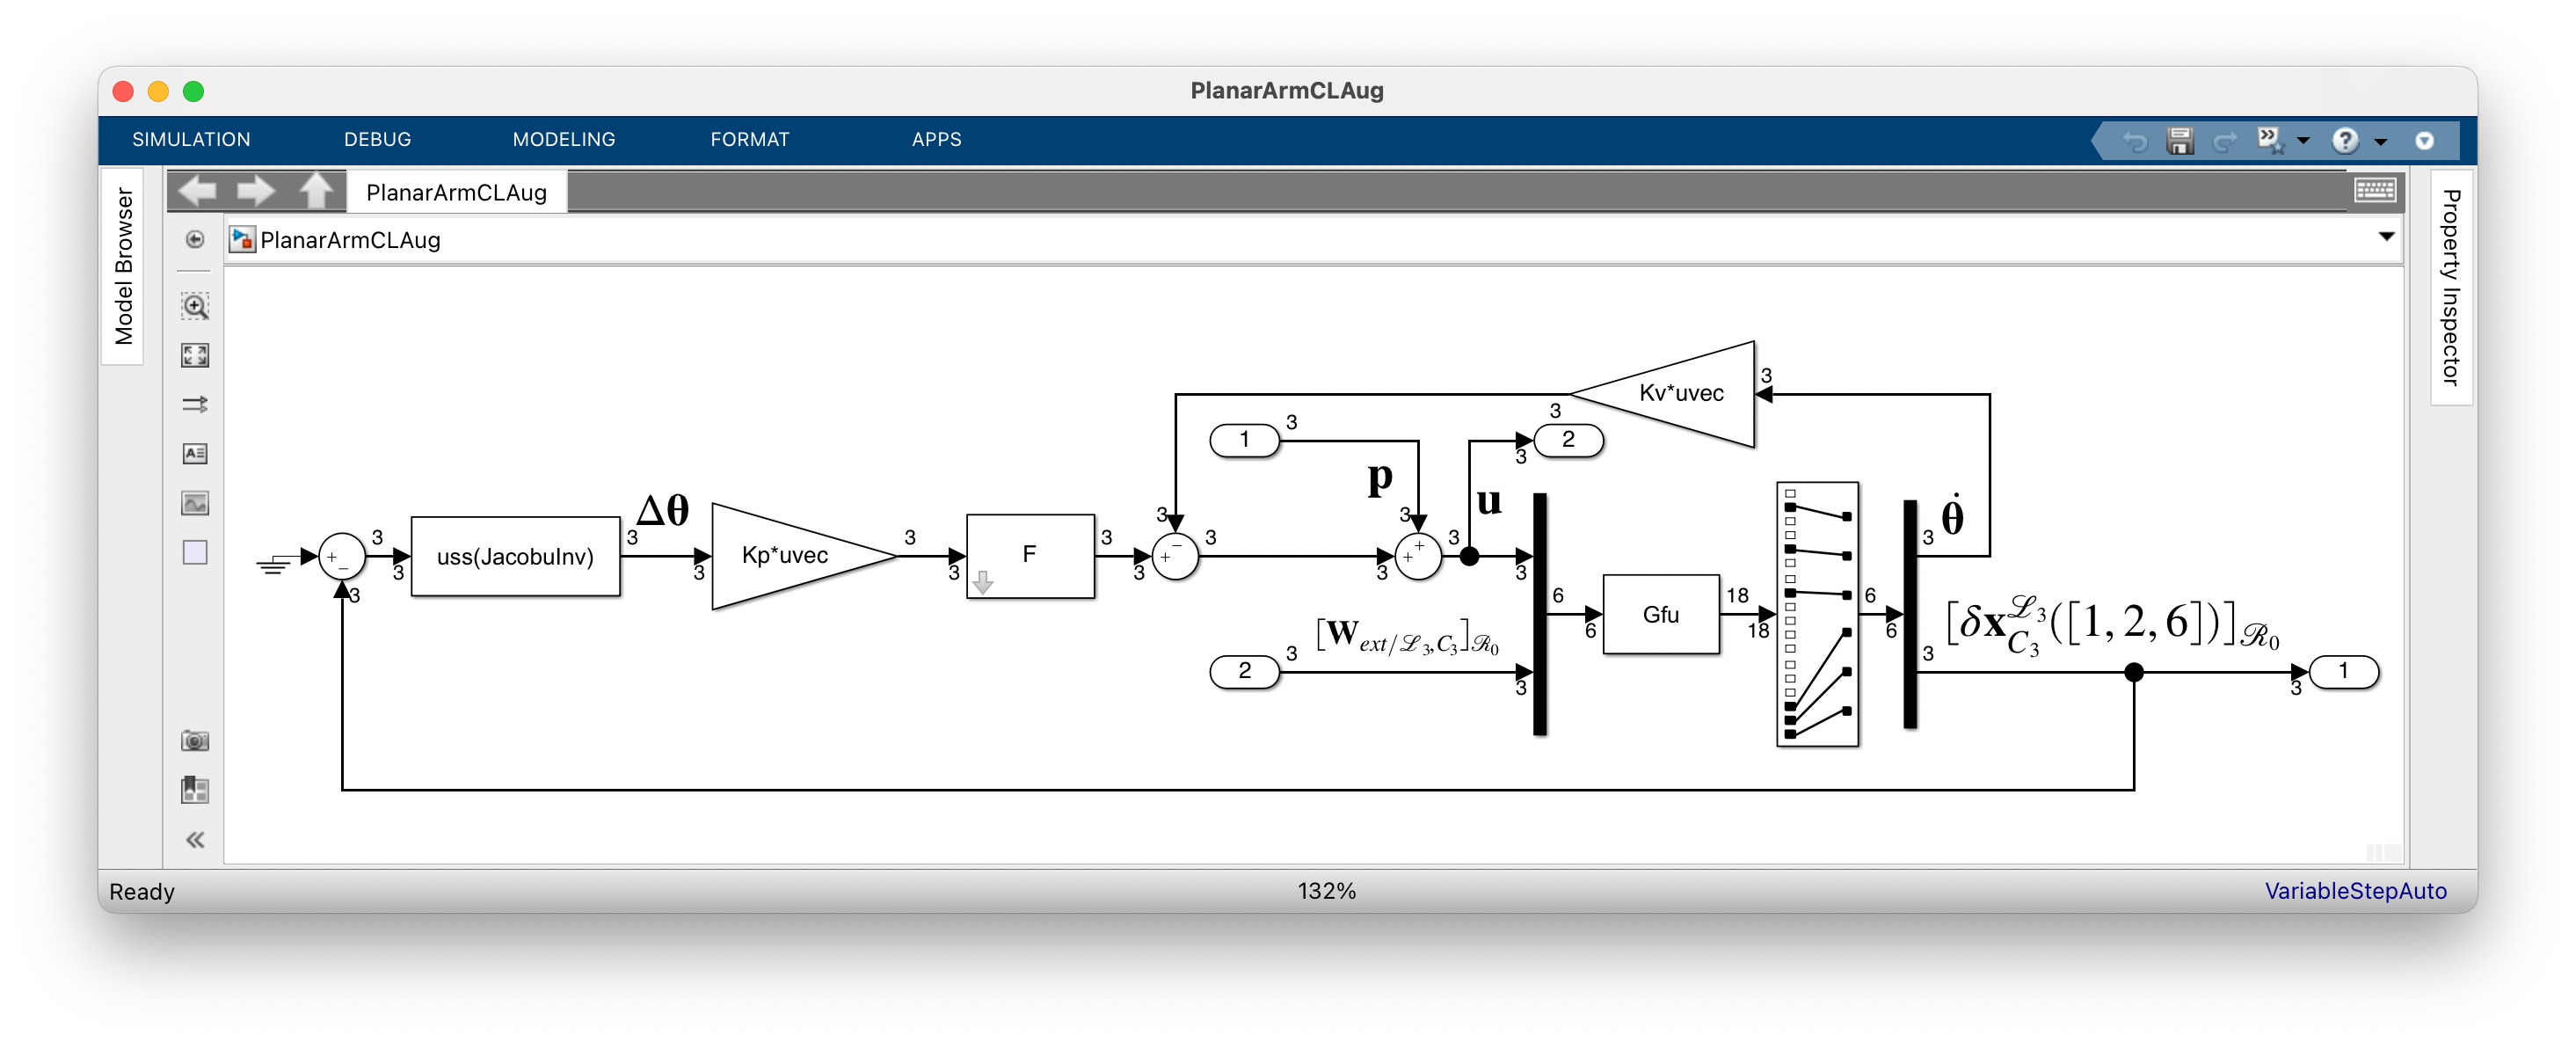

w=0.5;
Kp=diag(diag(I0)*w^2);
Kv=1.4*diag(diag(I0)*w);
F=tf(10*w,[1 10*w])*eye(3);
PlanarArmCLAug
CLu=ulinearize('PlanarArmCLAug');
CLu=simplify(CLu,'full')

CLu =

  Uncertain continuous-time state-space model with 6 outputs, 6 inputs, 39 states.
  The model uncertainty consists of the following blocks:
    tan_theta1_div4: Uncertain real, nominal = 0.199, range = [-1,1], 8 occurrences
    tan_theta2_div4: Uncertain real, nominal = -0.414, range = [-1,1], 20 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0.199, range = [-1,1], 20 occurrences

Type "CLu.NominalValue" to see the nominal value, "get(CLu)" to see all properties, and "CLu.Uncertainty" to interact with the uncertain elements.



Note that the proposed control law depends on $\mathbf J^{-1}(\mathbf\theta)$ and it is therefore necessary to ensure that the Jacobian $\mathbf J(\mathbf\theta)$ is free from singularities in the working domain. One can use the parametric robustness analysis tools for this task by looking for the worst-case gain of $\mathbf J^{-1}(\mathbf\theta)$:

[WCG,WCU] = wcgain(ss(inv(Jacobu)))

WCG = struct with fields:
           LowerBound: Inf
           UpperBound: Inf
    CriticalFrequency: 0


WCU = struct with fields:
    tan_theta1_div4: -0.2285
    tan_theta2_div4: -4.6184e-12
    tan_theta3_div4: -0.2335


Indeed, the Jacabian is singular when $\theta_2=0$.

Thus  it is recommanded to restrict the range of variation of $\theta_2$: $\theta_2\in[-3\pi/4,\quad -\pi/4]$:

Jacobu.Blocks.tan_theta2_div4.Range=[tan(-3*pi/16) tan(-pi/16)]

Jacobu =

  Uncertain matrix with 3 rows and 3 columns.
  The uncertainty consists of the following blocks:
    tan_theta1_div4: Uncertain real, nominal = 0.199, range = [-1,1], 4 occurrences
    tan_theta2_div4: Uncertain real, nominal = -0.414, range = [-0.668,-0.199], 36 occurrences
    tan_theta3_div4: Uncertain real, nominal = 0.199, range = [-1,1], 34 occurrences

Type "Jacobu.NominalValue" to see the nominal value, "get(Jacobu)" to see all properties, and "Jacobu.Uncertainty" to interact with the uncertain elements.



[WCG,WCU] = wcgain(ss(inv(Jacobu)))

WCG = struct with fields:
           LowerBound: 1.5580
           UpperBound: 42.7635
    CriticalFrequency: 0


WCU = struct with fields:
    tan_theta1_div4: -0.8744
    tan_theta2_div4: -0.4979
    tan_theta3_div4: -0.6630


Now, it is ensured that the jacobian $\mathbf J(\mathbf\theta)$ is never singular on the new working domain and can analyze the proposed control law on this domain:

CLu.Blocks.tan_theta2_div4.Range=[tan(-3*pi/16) tan(-pi/16)];

One can then plot:

- the frequency domain response of the input sensivity function corresponding to the tranfert from $\mathbf p$ to $\mathbf u$:

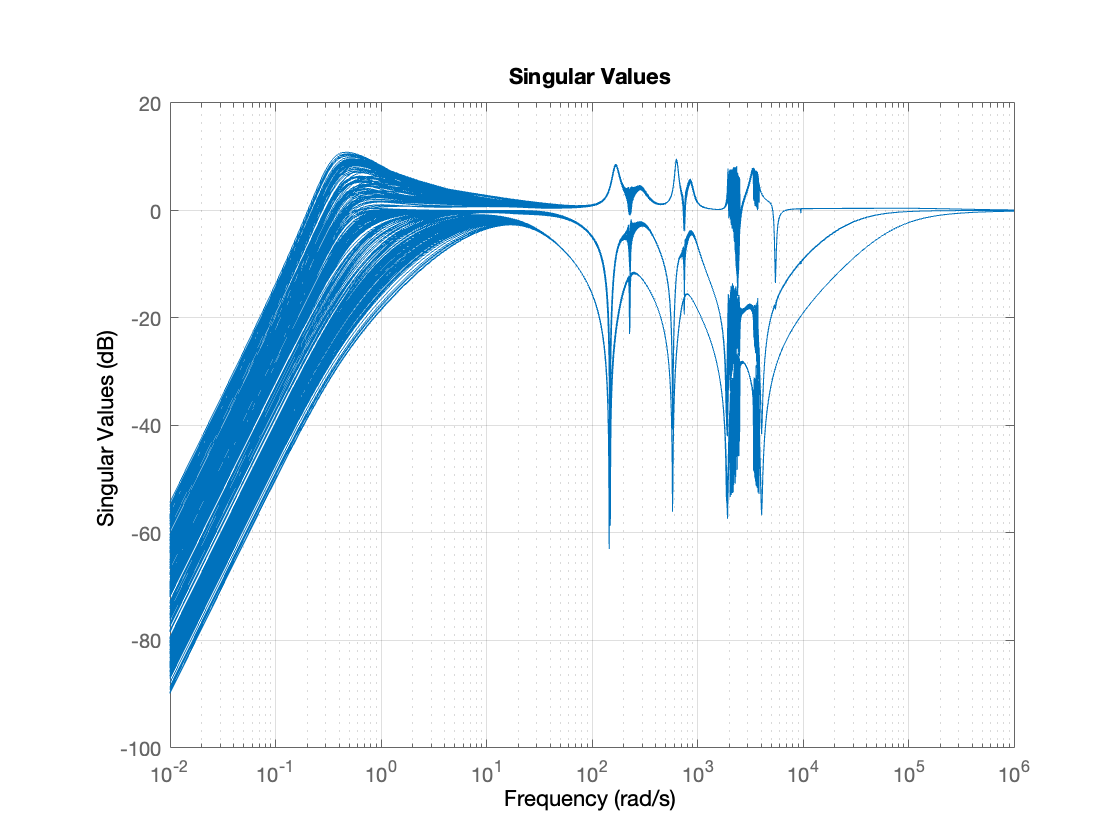

figure
sigma(usample(CLu(4:6,1:3),100))
grid

- the closed-loop response of $[\Delta\mathbf x_{C_3}]_{\mathcal R_0}$  to impulses on $[\mathbf W_{ext/\mathcal L_3,C_3}]_{\mathcal R_{0}}$ (valid only for small magnitude steps since the linear model is only valid for small variations around the nominal configuration)

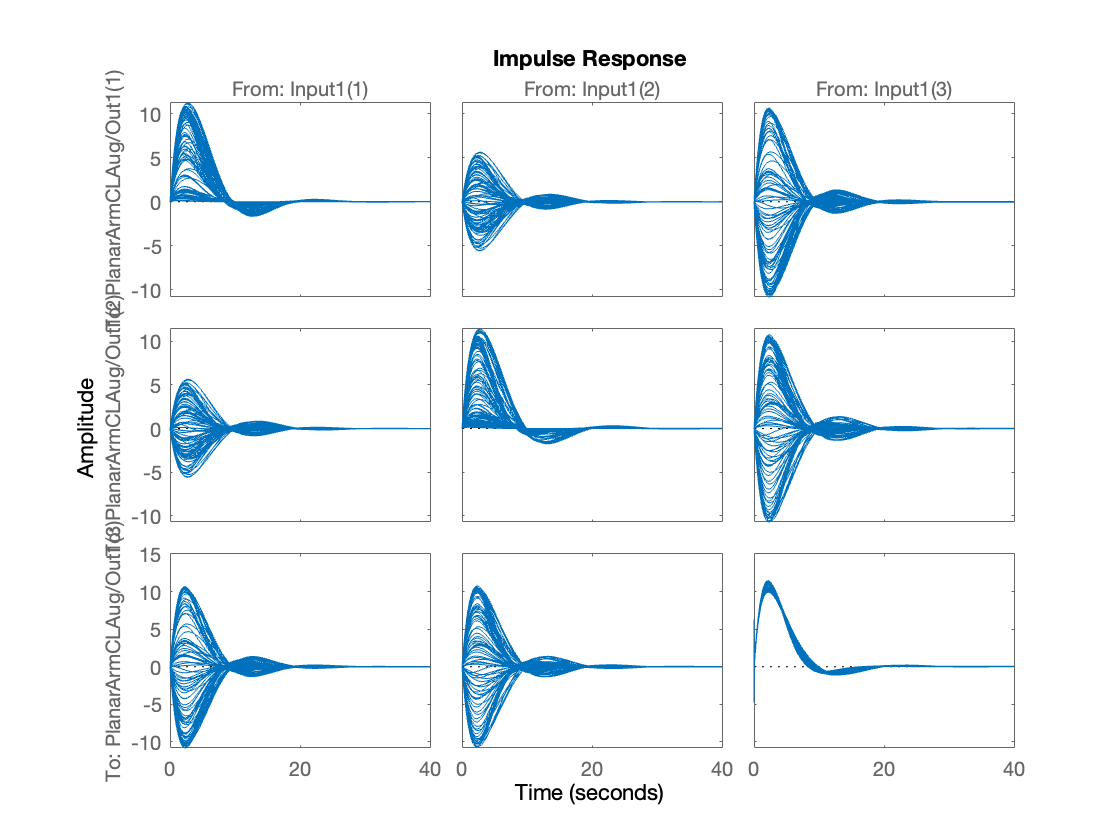

figure
impulse(usample(CLu(1:3,4:6),100))

One can check on the frequency domain response of the input sensitivity function that the low frequency response is sensitive to the geometric configuration $\mathbf\theta$ and can reach $11\,dB$ . Thus it could be also recommanded to adapt the gains $\mathbf K_p$ and $\mathbf K_v$ to the geometric configuration. That can be easily done by computing the apparent inertia $\mathbf I(\mathbf\theta)$ seen from the 3 joints and using the LPV gains: $\mathbf K_p(\mathbf\theta)=\omega_c^2\,\mathbf I(\mathbf\theta)$ and $\mathbf K_v(\mathbf\theta)=1.4\omega_c\,\mathbf I(\mathbf\theta)$:

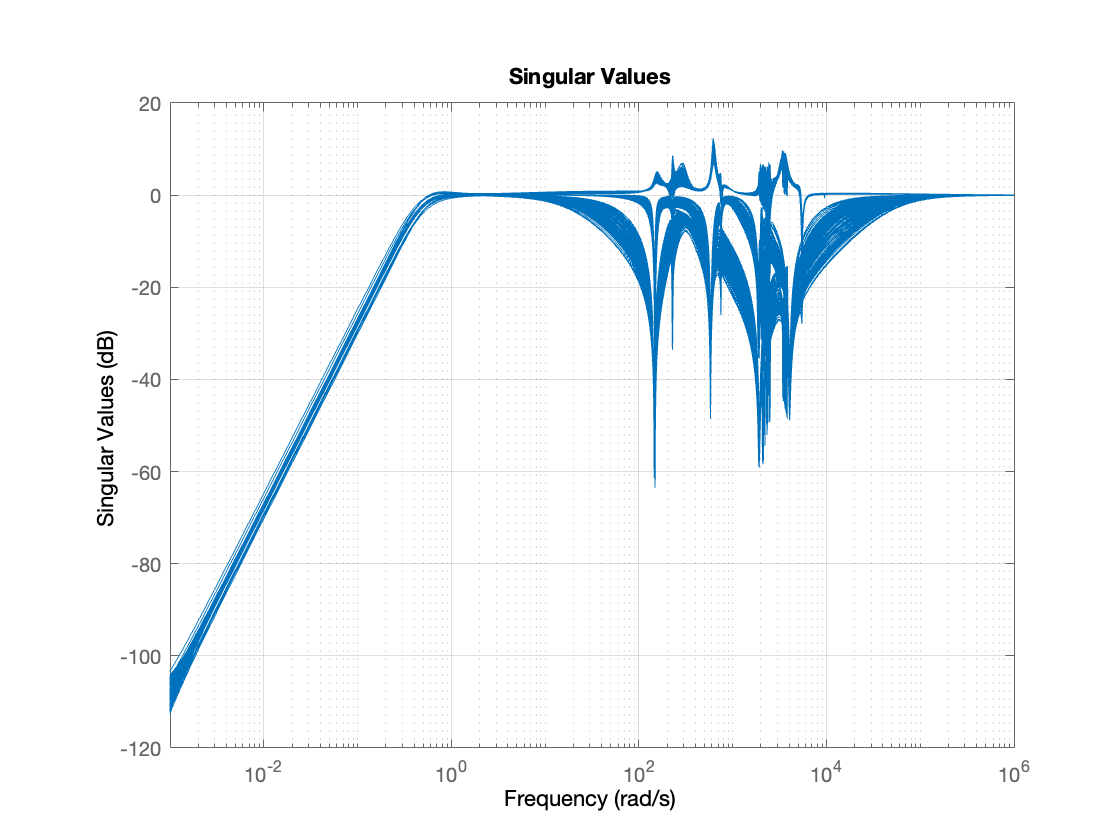

Itheta=inv(Gu.d(1:3,1:3)-Gu.c(1:3,:)*inv(Gu.a)*Gu.b(:,1:3));
Itheta=simplify(Itheta,'full');
Kp=w^2*Itheta;
Kv=1.4*w*Itheta;
PlanarArmCL_LPV_Aug
CLu=ulinearize('PlanarArmCL_LPV_Aug');
CLu=simplify(CLu,'full');
CLu.Blocks.tan_theta2_div4.Range=[tan(-3*pi/16) tan(-pi/16)];
figure
sigma(usample(CLu(4:6,1:3),100))
grid

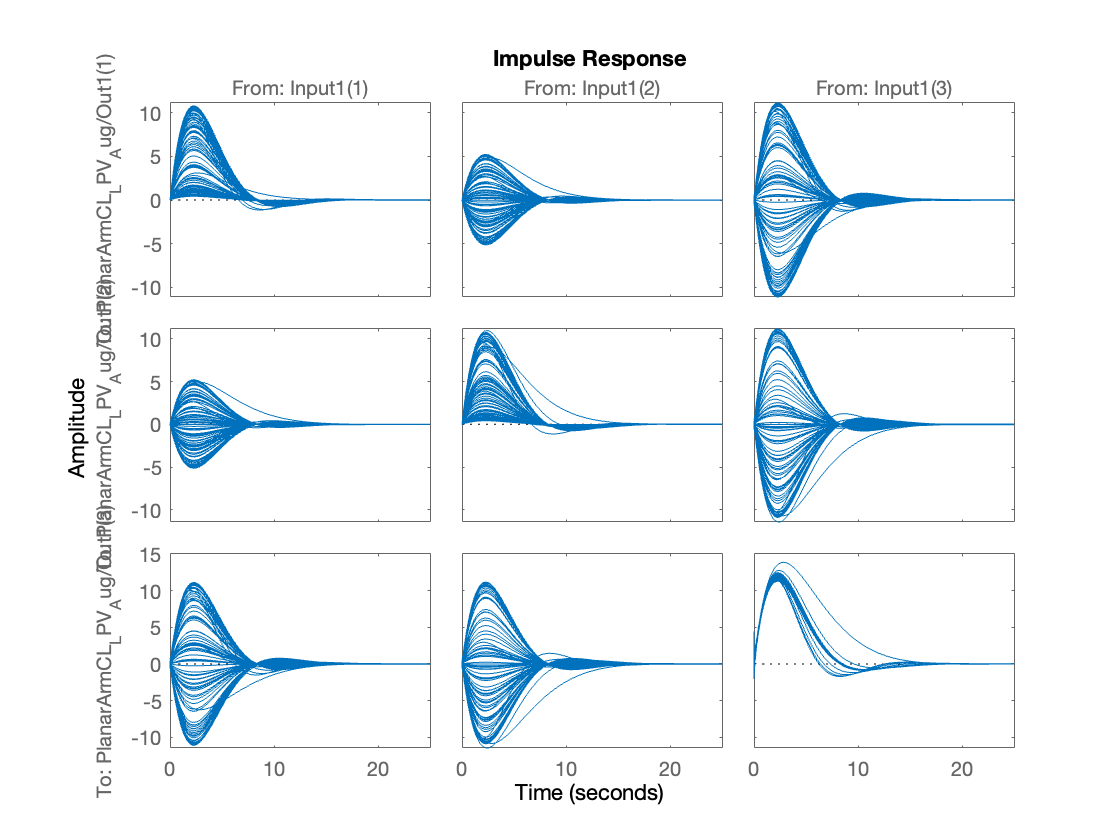

figure
impulse(usample(CLu(1:3,4:6),100))

Now the low frequnecy response of the input sensitivity function is insensitive to the geometric configuration but the disc margin is now imposed by a flexible mode around $\approx 600\,rad/s$. 

The main objective of this tutorial was to highlight the interest, for robotics engineering, to work with models fully parametrized according to the geometric configuration.